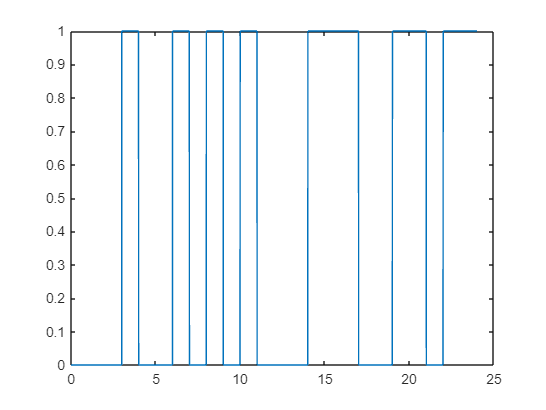


T = 24;              %segundos
Ts = (0.001)/2;     %segundos/muestra
t = 0:Ts:T;          %vector tiempo de muestreo

f((t>0)&t<=3)=0;
f((t>3)&(t<=4))=1;
f((t>4)&(t<=6))=0;
f((t>6)&(t<=7))=1;
f((t>7)&(t<=8))=0;
f((t>8)&(t<=9))=1;
f((t>9)&(t<=10))=0;
f((t>10)&(t<=11))=1;
f((t>11)&(t<=14))=0;
f((t>14)&(t<=17))=1;
f((t>17)&(t<=19))=0;
f((t>19)&(t<=21))=1;
f((t>21)&(t<=22))=0;
f((t>22)&(t<=24))=1;
plot(t,f)

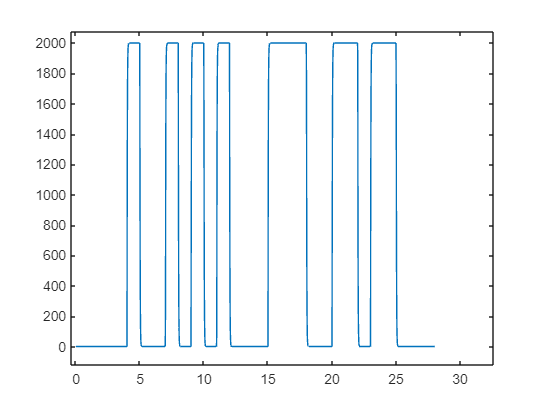


%Convolucion con la funcion de simulink
ht = out.simout.data;
t1 = out.simout.time;
y2 = conv(f,ht,'full'); 
time2 = t1(1)+t(1):0.001/2:t1(end)+t(end);
plot(time2,y2)

#### b) Tome la señal que usted construyó en la Tarea 2, x(t). Encuentre la respuesta de la convolución y(t) = x(t) * h(t). ¿Qué observa respecto a la forma de la señal y(t) en cuanto a forma y duración? Es decir, ¿la señal y(t) es diferente a la señal x(t)?

Al graficar la función de la convolución se observa que la forma de y(t) es muy parecida a la f(t) del color, pero aumentando la amplitud (note que aumenta de 1 a 2000). Esto es debido a que el valor de $\tau$ es pequeño ($\tau$ = 1/50) , ya que de tener un valor mayor, por ejemplo de $\frac{1}{2}$, la forma cambia ligeramente con respeco a f(t). En cuanto a duración, se puede observar que es casi la misma, pero al ser la convolución, se toma el tiempo inicial de f(t) y se le suma el tiempo inicial de la simulación que genera h(t), lo cual es 0, y se hace lo mismo con los tiempos finales (24+4) y por esta razón el tiempo de la convolución es 28.

#### c) Con base en el ancho de las señales, ¿Es posible obtener la respuesta de una sola componente de color?

Como las gráficas de las señales son tan parecidas y ambos tiempos de simulación comienzan en 0, es sencillo obtener una de las componentes del color, tomanto el valor de y(t) cada 8 'tiempos', que daría el valor del bit.

Por ejemplo, si necesitamos la primera componente del color, según la gráfica de la convolución esta sería los valores de y(t) con t discreto de 0 a 7, y así:

R = 00010010                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             